# Processing PAX1000 polarimeter LTM data

; tabulated .csv files are identified by path and file name (optionally indexing used in file name). Input file names without extension. Choose the quantity under inspection. Then in case of an erroneous function call an error message lists possible choices. The algorithm attempts to sort the measurement result into series of lower and higher estimators in case of oscillatory measurement results. Meanwhile outlying and high jitter results are filtered. During operation results are plotted. In case of constant values it's efficient to calculate modes of respective data series for reading off estimators accurately. This script serves to process data as well as to store thus read off values.

## Select files

Cell `path` contains the paths to LTM result files, `indices` contains file names (as index strings), `aux` an auxiliary string (but not the .csv extension) to be appended after the `indices` value in each file name.

path=cell(1,14);
indices=cell(14,1);
aux='';
path{1}='meas1.2/1-5050/';
path{2}='meas1.2/2A-9010/';
path{3}='meas1.2/2B-9010/';
path{4}='meas1.2/2C-9010/';
path{5}='meas1.2/2C-9010/';
path{6}='meas1.2/3-9901/';
path{7}='meas1.3/0PBS-A/';
path{8}='meas1.3/0PBS-B/';
path{9}='meas1.3/0PBS-C/';
path{10}='meas1.3/0PBS-D/';
path{11}='meas1.2/4A-FM/';
path{12}='meas1.2/4B-FM/';
path{13}='meas1.3/1FM-A/';
path{14}='meas1.3/1FM-B/';
indices(1,1:12)={'1-IJ','2-IS','3-IT','4-JS','5-JT','6-ST','7-JI','8-SI',...
    '9-TI','10-SJ','11-TJ','12-TS'};
indices(2,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(3,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(4,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(5,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(6,1:6)={'1-IS','2-IT','3-ST','4-SI','5-TI','6-TS'};
indices(7,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(8,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(9,1:6)={'1-31','2-32a','2-32b','3-12','4-13','5-23'};
indices(10,1:7)={'1-31','2-32a','2-32b','3-12','4-13','5-23','6-21'};
indices(11,1:2)={'D12','D21'};
indices(12,1:2)={'D12','D21'};
indices(13,1:2)={'D12','D21'};
indices(14,1:2)={'D12','D21'};

## Select quantity under inspection

As an example we inspect optical power measured in dBm.

inputname='logp';

## Set filtering parameters

Variable `trend` is needed for optimization of filtering. -1 means monotonously decreasing, 0 constant and 1 monotonously increasing quantity. Parameter `tolerance` defines how many times the computing precision is a lower limit for a step size in the measurement result for a step to be considered the effect of oscillating value; for logarithmic power measurement this is typically a value under 3. `pround` is a parameter that describes computing precision: measurement data will be rounded to this many digits.

trend=0;
tolerance=1;
pround=3;

## Call function `createparam`

Give parameters to the data processing function in the order of creation here. It's advised to store the results in the following way: let cell `unprocessed` store the raw data, `tv` the timestamps of recording separately, compared to the LTM start time, in ms, cell `processed` the values that are filtered, i. e. sorted into lower and higher etimator series, finally cell `tvp` the timestamps corresponding to filtered values adjusted to jitter-free sampling instances (at least where the actual sampling instances differed little enough from jitter-free sampling).

unprocessed=cell(1,14);
tv=cell(1,14);
processed=cell(1,14);
tvp=cell(1,14);

The plots created during data processing help fine tune the value of `tolerance`, this occasionally eliminates erroneous processing.

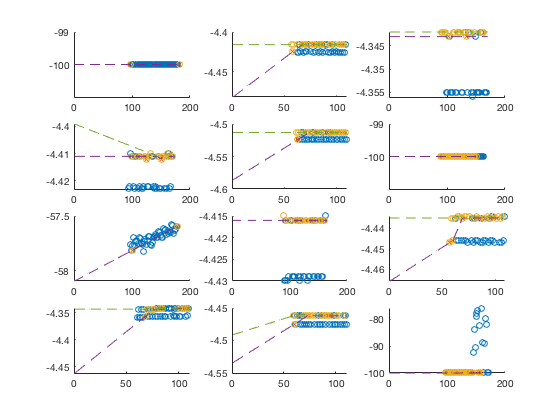

i=1;
[unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);

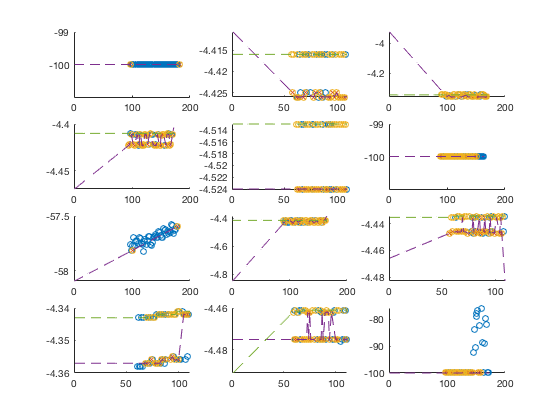

tolerance=1.79;
[unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);

## Parse and store results of processing

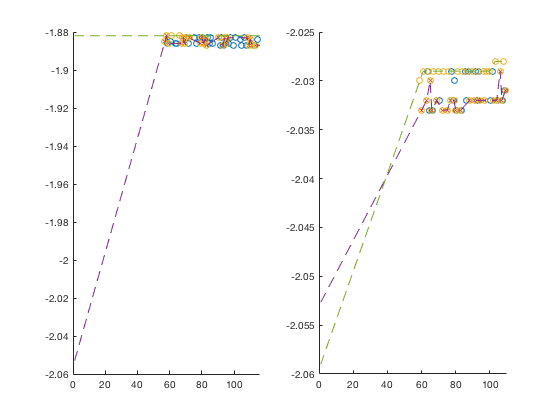

i=14;
tolerance=2.5;
try
    [unprocessed{i},tv{i},processed{i},tvp{i}]=createparam(path(i),indices(i,...
    1:lastnonempty(indices(i,:))), aux, inputname, trend, tolerance,pround);
catch ME
    if strcmp(ME.identifier,'MATLAB:griddedInterpolant:DegenerateGridErrId')
        warning('tolerance not OK.');
    else
        error(ME.message);
    end
end

Here by continuing processing sweeping from 2 to 14 result cells are filled and plots are generated. Then itbecomes apparent that the first 45 elements of raw data are discarded by the algorithm, this has to be counted with performing sweeping measurements e. g. when characteristics are to be recorded. Furthermore filtered data is sorted into the lower estimator "more aggressively," so this sometimes contains outlying values that belong to the higher one, this suggests calculating modes of estimators is useful.

processedmodes=modecounting(processed);
processedmodes

processedmodes = 1×1 cell array
    {2×12 double}


Thus processing for one quantity is concluded. In order to read off more accurately, function `modecounting` doesn't simply compute the modes, nstead it uses them to identify the adequate estimator for a measured constant quantity. The operation of this was tested for lower estimators, so storing these follows next.

## Save

if ~isfile('res/logp.mat')
save res/logp.mat aux indices inputname path processed ...
    processedmodes pround trend tv tvp unprocessed
else
    error('file res/logp.mat exists, aborting');
end

file res/logp.mat exists, aborting

It's advised to save the modes of one, e. g. the lower one of the estimators in .csv format, too, for convenient processing and LaTeX.

if ~isfile('res/logp.csv')
pm2=cell(1,length(processedmodes));
maxi=0;
for i=1:length(processedmodes)
    vector=processedmodes{1,i};
    if length(vector)>maxi
        maxi=length(vector);
    end
    pm2{1,i}=vector(1,:)';
end
    vector=nan(maxi,length(pm2));
    for j=1:length(pm2)
    vector(1:length(pm2{1,j}),j)=pm2{1,j};
    end
for i=1:maxi
    dlmwrite('res/logp.csv',vector(i,:),'-append','delimiter',',');
end
else
    error('file res/logp.csv exists, aborting');
end